% *************************************************************
% GMCM2019 D Code
%   Construction of a driving cycle
%   1. Data cleaning and preprocess
%   2. Extract of micro trips
%   3. Construction of a representative cycle
% 
% Coded with MATLAB 2018a 
%
% Date: 2019/09/19
%
% Copyright: 
%   @Team 19102480128
%   Coded by Wanfeng Hu
% *************************************************************

clear

%% Read files and extract date
header = {'time','velocity','accelx','accely','accelz','longitude', ...
    'latitude','engine_revolution','torque_percentage','consumption', ...
    'pedal_opening','air_fuel_ratio','load','air_flow'};
filename = '';
max_try = 3;
while isempty(filename) && max_try > 0
    [file, path] = uigetfile('*.xlsx', 'Please select a data file for driving cylce construction');
    if file ~= 0
        filename = [path, file];
        break
    end
    max_try = max_try - 1;
end
if max_try == 0
    error("You have to select a file!")
end
rawdata = readtable(filename);

rawdata.Properties.VariableNames = header;
rawdata.time = datetime(rawdata.time, "InputFormat", "yyyy/MM/dd HH:mm:ss.SSS.");

%% Data cleaning and statistics
% Split raw data into pieces
idx = extract_slice(rawdata.velocity);

% Preprocess and statistics
min_revolution = 600;
interval = [10 20 40 80 140];
thresh = seconds(60);
len = length(idx);
z = zeros(len, 1);
d = struct('raw', z, 'raw_stats', z, 'processed', z, ...
    'stall', z, 'processed_stats', z, 'groupid', z, 'id', z);
for i = 1:len-1
    d(i).id = i;
    d(i).raw = rawdata(idx(i):idx(i+1)-1, :);
    d(i).raw_stats = statistics(d(i).raw);
    [d(i).processed, d(i).stall] = preprocess(d(i).raw, min_revolution, thresh);
    d(i).processed_stats = statistics(d(i).processed);
    % Assign groupid based on its max velocity
    d(i).groupid = segregate2group(d(i).processed_stats, interval);
end

%% Construction of driving cycle
global extract
extract = ExtractStats;
Trep = 1200;
Tfull = sum(extract.total_time(d));
Tdrive = sum(extract.total_drive_time(d));
len_interval = length(interval) - 1;
bincounts = 5;
idle_interval = 30;

% For each group, select the most representative slices
selected_group = [];
for i = 1:4
    group = match_group(d, i);
    selected_group = cat(2, selected_group, select(group, Tfull, Trep, bincounts)); 
end

Having less than desired in a distance bin
Optimizing for the covered distance
No replacement



% Construction
rep_cycle = construct(d, selected_group, Trep, idle_interval);

Total idel time less than required
Still short of time


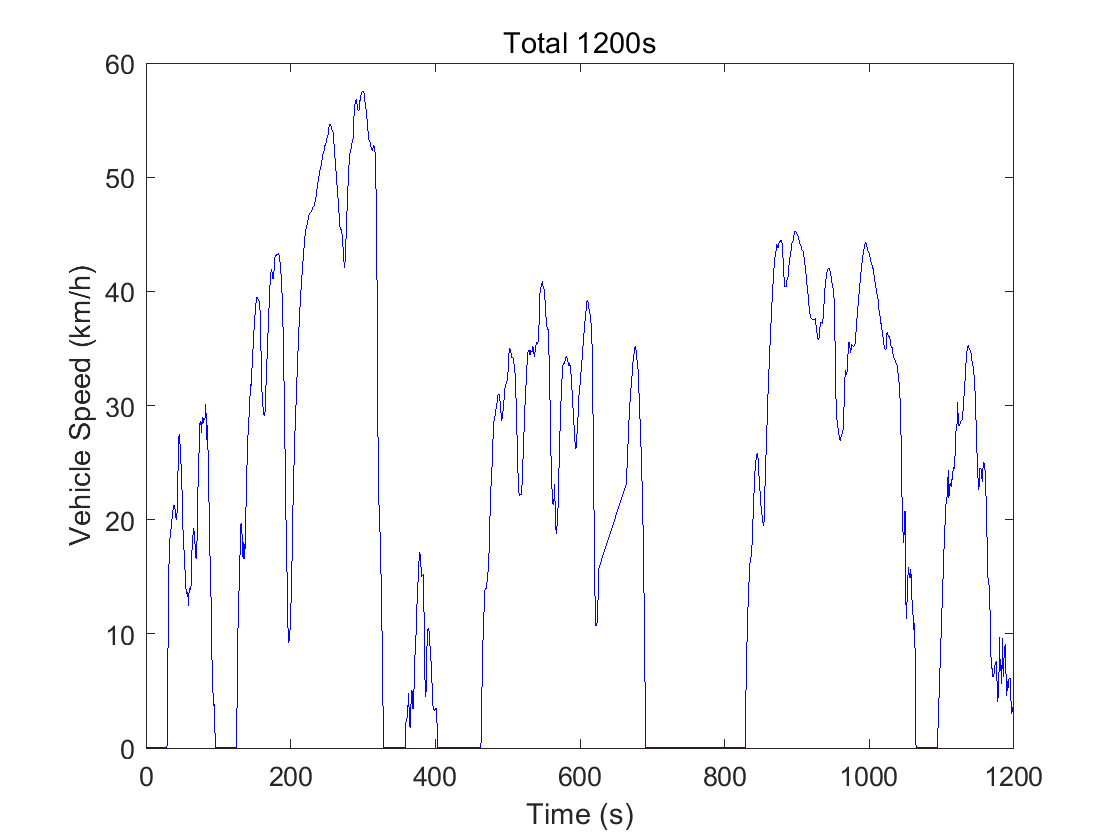

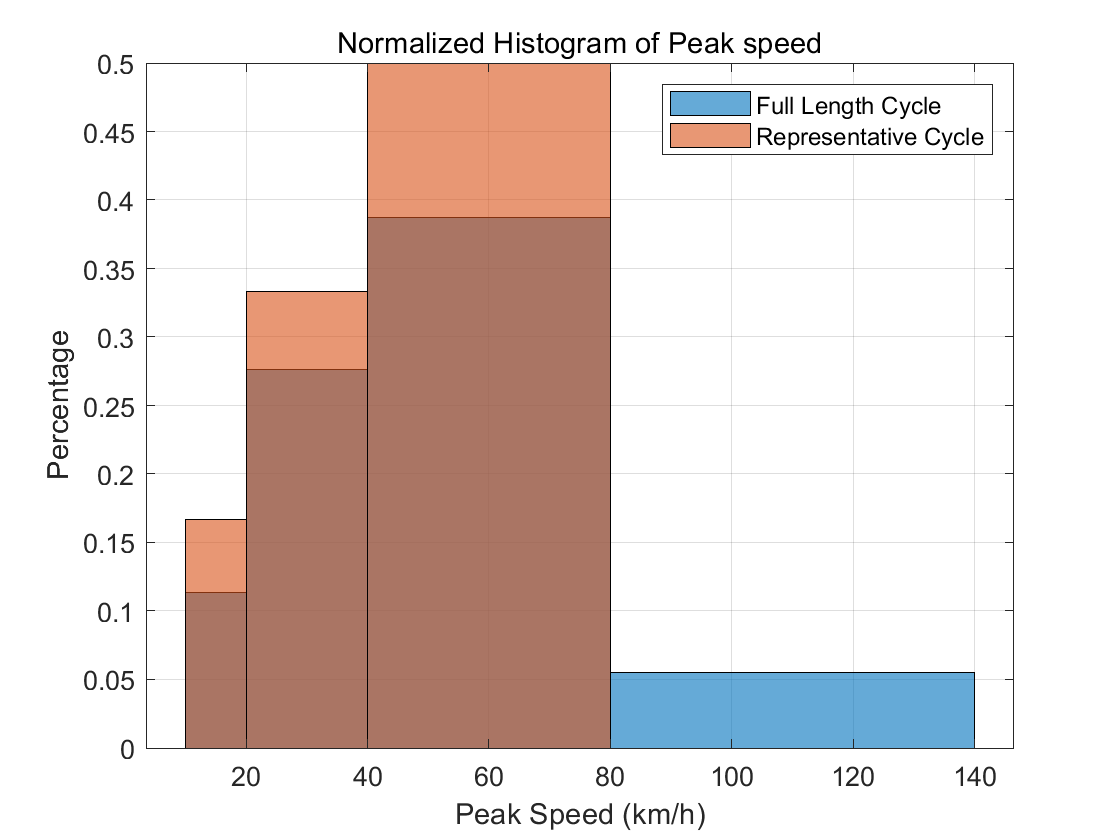

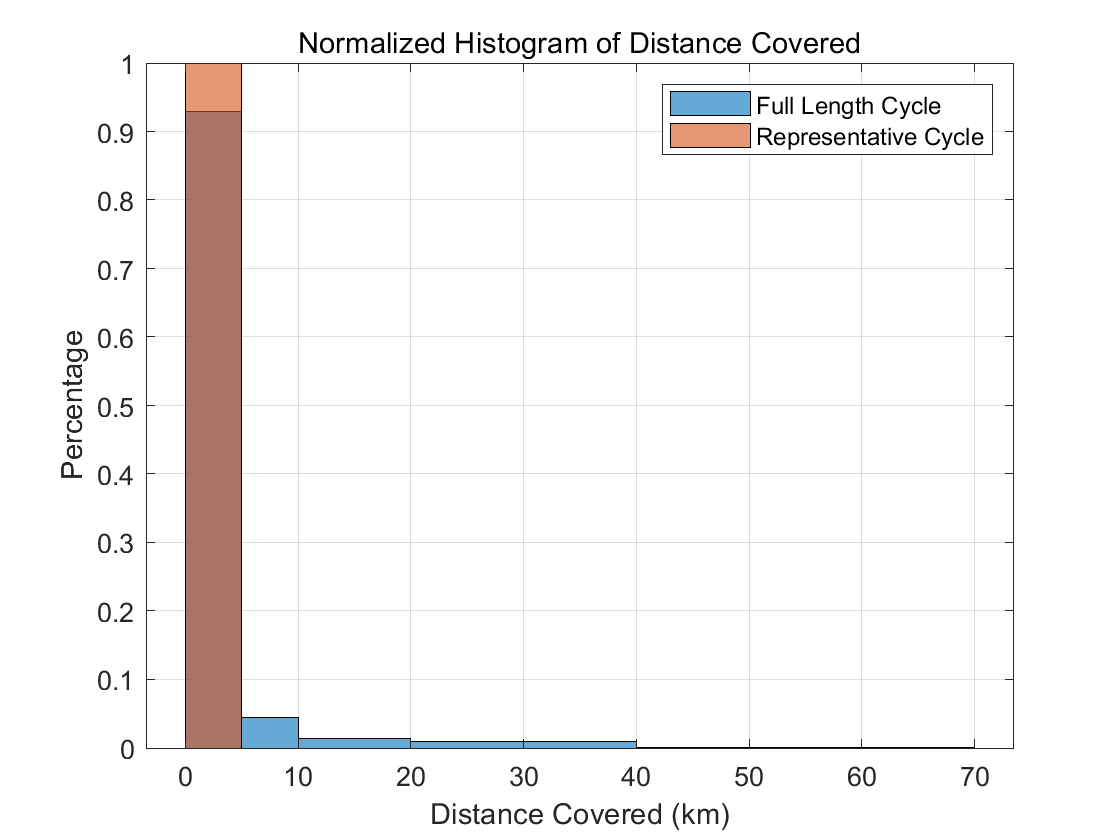

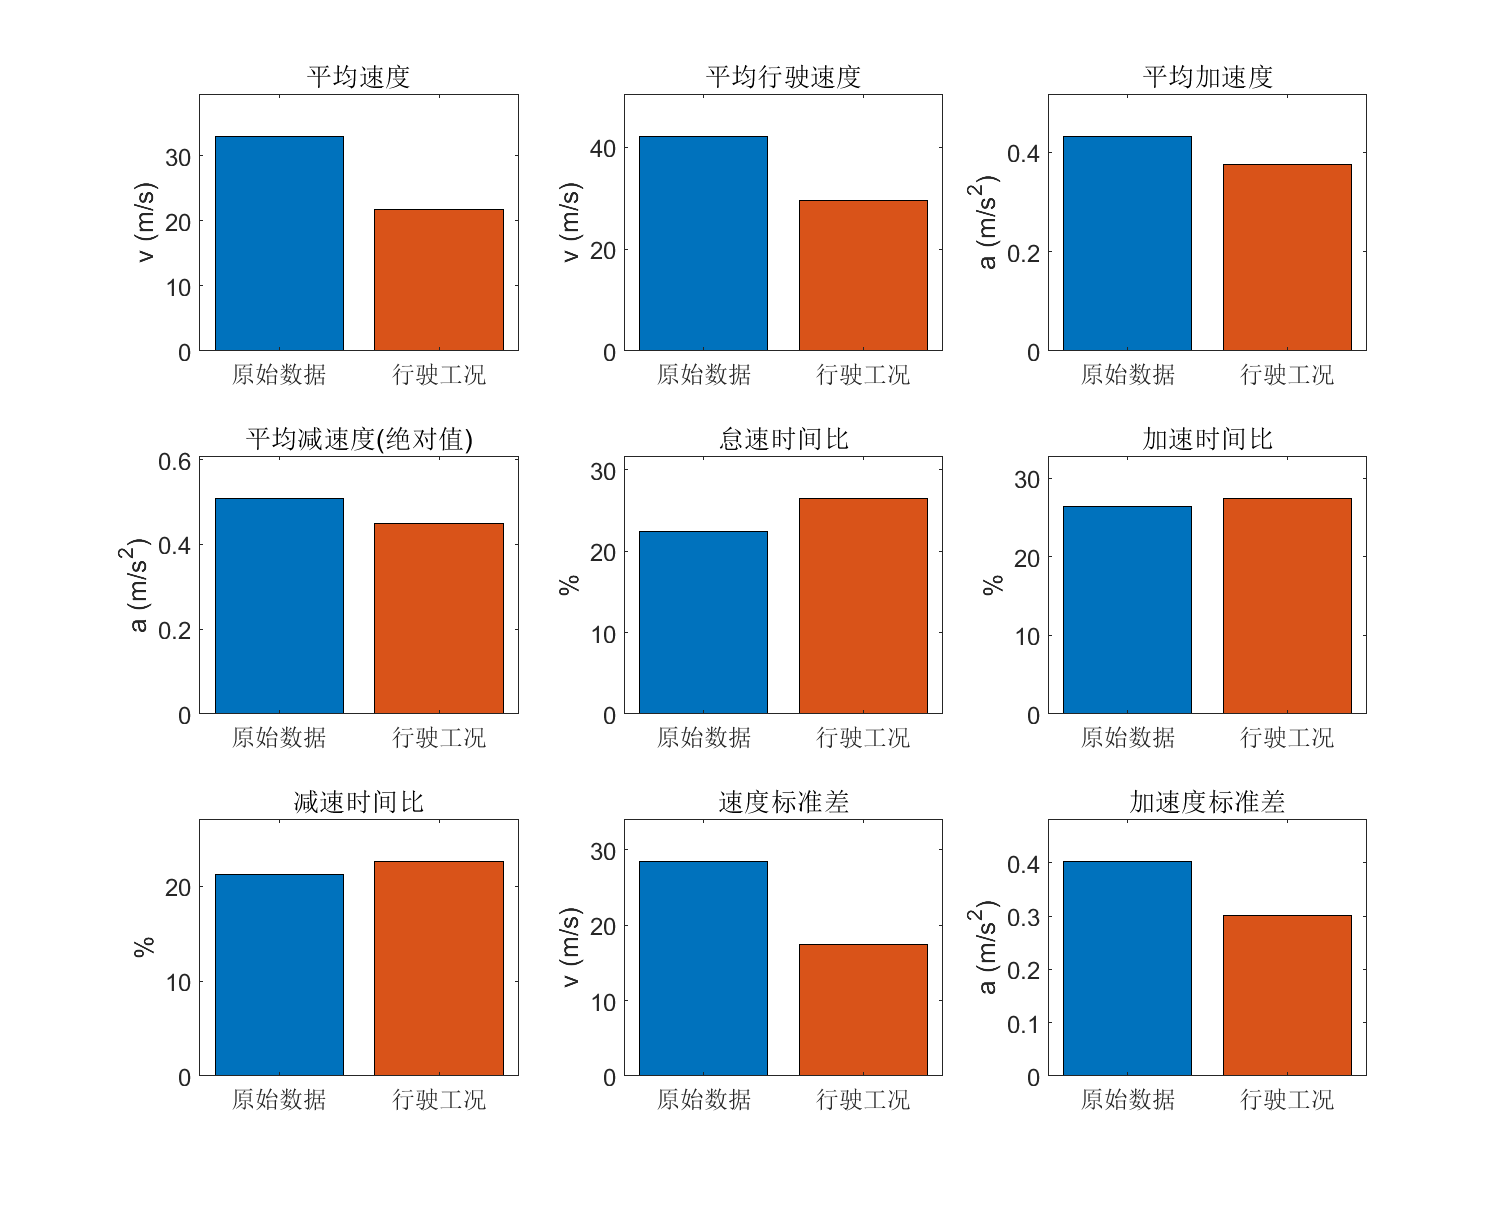

%% Postprocess
run('PostProcess.m')

%% Geo Map
% GPS Signal lost location
latitude_lost = rawdata.latitude == 0;
longitude_lost = rawdata.longitude == 0;
% Make sure they match
if ~all(latitude_lost == longitude_lost)
    disp("GPS signal lost data doesn't match!!!")
end

% Map the latitude and longitude
disp("Please make sure that you're connected to Internet!")

Please make sure that you're connected to Internet!


webmap('Open Street Map')
s = geoshape(rawdata.latitude(~latitude_lost), rawdata.longitude(~longitude_lost));
wmline(s,'Color', 'b', 'Width', 1);